# **Primero Cargamos los datos **

load("DATOS\twosat\Mediterraneo\Data_Anticiclonica_short_long_combinado.mat")
load("DATOS\twosat\Mediterraneo\Data_Cicllonica_short_long_combinado.mat")
% Show variables (fields) of the struct
fields = fieldnames(Data_ANC);

tipos={"Data_ANC","Data_CIC"};
% Encontrar los índices donde Data_ANC.celda no es 0
indicesAN = find(Data_ANC.celda ~=  0);
for var_name = fields'
    var_name = var_name{1};
    [rows, cols] = size(Data_ANC.(var_name));
    if cols<2
        Data_ANC.(var_name) = Data_ANC.(var_name)(indicesAN, :);
    else
        % En el caso de variables 3D (lat, lon, tiempo u otras dimensiones)
        Data_ANC.(var_name) = Data_ANC.(var_name)(:, indicesAN);
    end
end

% Encontrar los índices donde Data_ANC.celda no es 0
indicesCIC = find(Data_CIC.celda ~=  0);
for var_name = fields'
    var_name = var_name{1};
    [rows, cols] = size(Data_CIC.(var_name));
    if cols<2
        Data_CIC.(var_name) = Data_CIC.(var_name)(indicesCIC,:);
    else
        % En el caso de variables 3D (lat, lon, tiempo u otras dimensiones)
        Data_CIC.(var_name) = Data_CIC.(var_name)(:, indicesCIC);
    end
end


# **Representación respecto lifetime Grafico Ciclonicos y Anticiclonicos**


SelectVariableY=fields(9);     % VARIABLE A REPRESENTAR 
SelectVariableX=fields(29);  
AnCiclonY= Data_ANC.(SelectVariableY{1}) ;  CiclonY= Data_CIC.(SelectVariableY{1}) ; 
AnCiclonX=Data_ANC.(SelectVariableX{1}) ; CiclonX=Data_CIC.(SelectVariableX{1}) ;


% Convertir a double para evitar errores de tipo
AnCiclonX = double(AnCiclonX);
AnCiclonY = double(AnCiclonY);
CiclonX = double(CiclonX);
CiclonY = double(CiclonY);

### Tratamiento Datos, convierta double, ordena y hace media para hacer ajuste polinomico

#### `Datos Anticiclonicos`


% Ordenar AnCiclonX y aplicar el mismo orden a AnCiclonY
[AnCiclonX, idx_ANC] = sort(AnCiclonX);  
AnCiclonY = AnCiclonY(idx_ANC);

% Encontrar los índices de los valores únicos en AnCiclonX
[AnCiclonX_avg, ~, idxUnique] = unique(AnCiclonX);

% Inicializar el vector para las medias
AnCiclonY_avg = zeros(size(AnCiclonX_avg));

% Calcular la media de AnCiclonY para cada valor único de AnCiclonX
for i = 1:length(AnCiclonX_avg)
    AnCiclonY_avg(i) = mean(AnCiclonY(idxUnique == i));
end


#### `Datos Ciclonicos`


% Ordenar CiclonX y aplicar el mismo orden a CiclonY
[CiclonX, idx_CIC] = sort(CiclonX);  
CiclonY = CiclonY(idx_CIC);

% Encontrar los índices de los valores únicos en AnCiclonX
[CiclonX_avg, ~, idxUnique] = unique(CiclonX);

% Inicializar el vector para las medias
CiclonY_avg = zeros(size(CiclonX_avg));

% Calcular la media de AnCiclonY para cada valor único de AnCiclonX
for i = 1:length(CiclonX_avg)
    CiclonY_avg(i) = mean(CiclonY(idxUnique == i));
end


### Representación

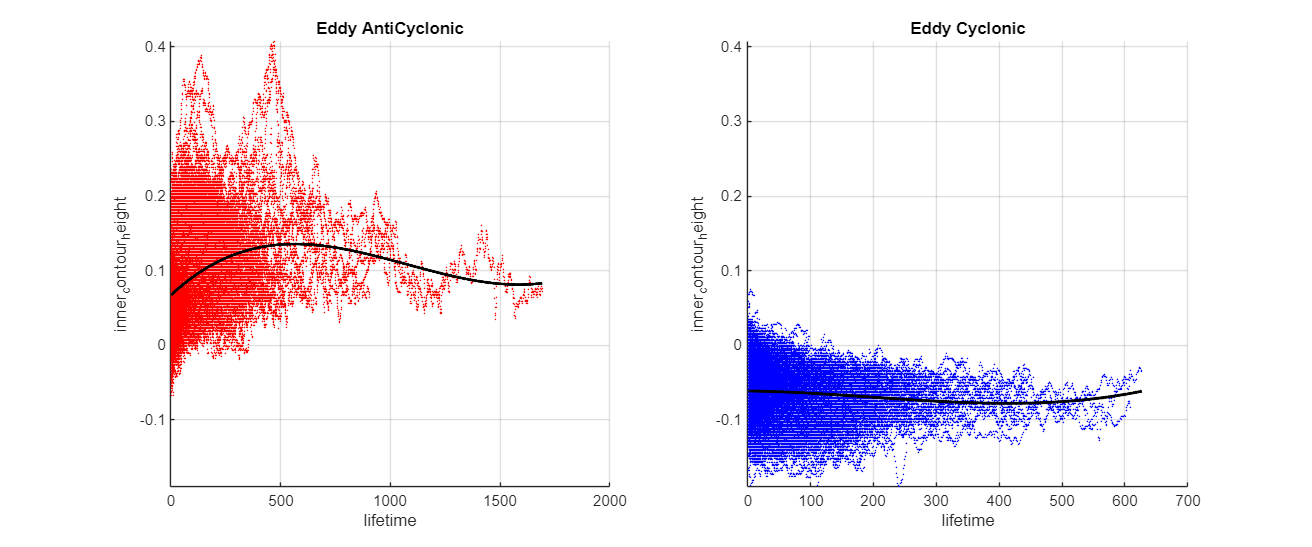

figure;
% Encontrar el valor mínimo y máximo entre ambas listas
minY = min([min(AnCiclonY), min(CiclonY)]);
maxY = max([max(AnCiclonY), max(CiclonY)]);

set(gcf, 'Position', [100, 100, 1200, 500]);
subplot(1,2,1); % (Filas, Columnas, Índice)
scatter(AnCiclonX,AnCiclonY,1, 'filled','MarkerFaceColor', "red")  
% Calcular la regresión lineal
[yFitAN, bestModel_AN]= EvaluaMejorPolinomio(AnCiclonX_avg, AnCiclonY_avg,3); % Evaluar la función ajustada


hold on
% Graficar la línea de regresión
plot(AnCiclonX_avg, yFitAN, 'black-', 'LineWidth', 2)
hold off
grid on
title("Eddy AntiCyclonic")
xlabel(SelectVariableX{1})
ylabel(SelectVariableY{1})
ylim([minY, maxY]);


subplot(1,2,2); 
scatter(CiclonX,CiclonY,1, 'filled','MarkerFaceColor', "blue")  
% Calcular la regresión lineal
hold on
[yFit_CIC, bestModel_CIC]= EvaluaMejorPolinomio(CiclonX_avg, CiclonY_avg,3); % Evaluar la función ajustada
plot(CiclonX_avg, yFit_CIC, 'black-', 'LineWidth', 2)
hold off
xlabel(SelectVariableX{1})
ylabel(SelectVariableY{1})
ylim([minY, maxY]);
grid on

title("Eddy Cyclonic")

# **Representación frecuencia LifetimeMax Grafico Ciclonicos y Anticiclonicos**

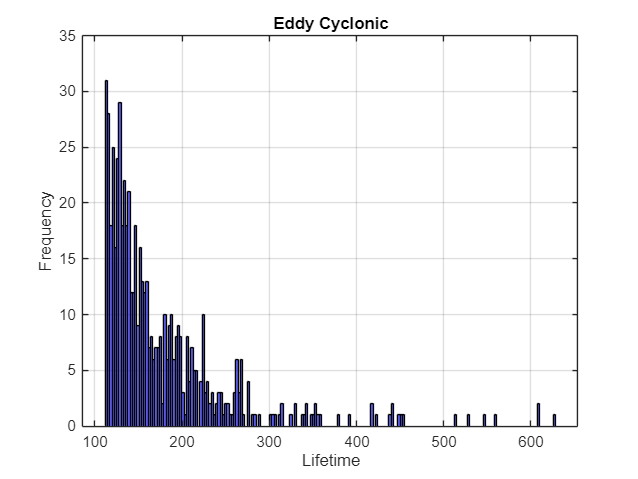

SelectTipo=tipos(2); 
if SelectTipo{1}=="Data_ANC"
    Titulo="Eddy Anticyclonic";
    color="red";
elseif SelectTipo{1}=="Data_CIC"
    Titulo="Eddy Cyclonic";
    color="blue";
end

% Get unique tracks
Lifetime = eval(SelectTipo{1}).lifetime;
Tracks = eval(SelectTipo{1}).track;
uniqueTracks = unique(Tracks);  % Find unique track values

% Loop through each unique track value
newLifetime = [];  % Array to store the modified lifetime values
for j = uniqueTracks'
    % Find the indices where the track is equal to the current unique track value
    idx = find(Tracks == j);
    life = Lifetime(idx);  % Extract the lifetime values for this track
    vida_max = max(life); 
    if vida_max>7*16% Find the maximum lifetime for this track
     newLifetime = [newLifetime, vida_max];  % Append the maximum lifetime to the newLifetime array
    end
end
figure;

% Now you can use newLifetime to plot or further process the data
% Example of plotting a histogram:
histogram(newLifetime, 200, 'FaceColor', color, 'EdgeColor', 'k');
xlabel('Lifetime');
ylabel('Frequency');
title(Titulo);
grid on;